1-2 系统的传递函数      

num=7*[2 5];
den=conv(conv([1 0 0],[3 2]),conv([2 7 8],[4 5]));
model=tf(num,den)

model =
 
                    14 s + 35
  ---------------------------------------------
  24 s^6 + 130 s^5 + 277 s^4 + 254 s^3 + 80 s^2
 
Continuous-time transfer function.



datestr(now,21)

ans = 'Mar.26,2021 20:20:09'

1-4 传递函数的串联      

num1=[2];
den1=[1 3 2];
sys1=tf(num1,den1);

num2=[1 6];
den2=[1 2 5];
sys2=tf(num2,den2);

syss=series(sys1,sys2)

syss =
 
              2 s + 12
  --------------------------------
  s^4 + 5 s^3 + 13 s^2 + 19 s + 10
 
Continuous-time transfer function.



datestr(now,21)

ans = 'Mar.26,2021 20:22:56'

1-5 传递函数的并联

num1=[2 9];
den1=[4 7 2];
sys1=tf(num1,den1);

num2=[1 6];
den2=[1 7 1];
sys2=tf(num2,den2);
syss=parallel(sys1,sys2)

syss =
 
     6 s^3 + 54 s^2 + 109 s + 21
  ----------------------------------
  4 s^4 + 35 s^3 + 55 s^2 + 21 s + 2
 
Continuous-time transfer function.



datestr(now,21)

ans = 'Mar.26,2021 20:23:31'

1-6 传递函数反馈连接

num=[2 9];
den=[2 6 5];
sys=tf(num,den);
syss=feedback(sys,1,1)

syss =
 
      2 s + 9
  ---------------
  2 s^2 + 4 s - 4
 
Continuous-time transfer function.



syss=feedback(sys,1,-1)

syss =
 
      2 s + 9
  ----------------
  2 s^2 + 8 s + 14
 
Continuous-time transfer function.



datestr(now,21)

ans = 'Mar.26,2021 20:24:06'

1-8 二阶系统实例

a）`自然频率固定为ω``n``＝1，ζ＝0.1,0.3,0.7,1。编写程序绘制各单位阶跃响应曲线，计算ζ＝0.3时的最大超调量`Mp`Mp，峰值时间`tp`tp，调整时间`ts`ts和上升时间`tr`tr。`

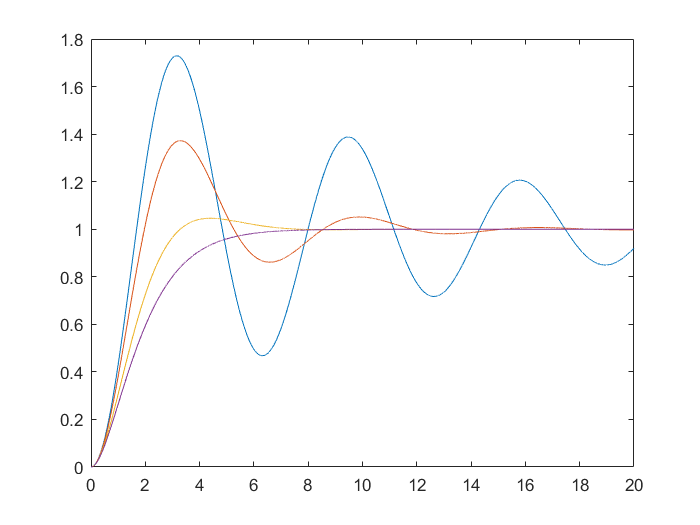

%%cser分别取0.1 0.3 0.7 1 
num=(1);
csei=[0.1 0.3 0.7 1];
s=0:0.001:20;
for i=1:4
den=[1 2*csei(i) 1];
sys=tf(num,den);
y(:,i)=step(sys,s);
end
plot(s,y)

%以下代码求解tp,ts,tr
[ymax,tprow]=max(y(:,2));
mp=ymax;
tp=tprow*0.001;
tes=find(abs(y(:,2)-1)<=0.05)*0.001;
ts=max(tes);
tr1=find(abs(y(:,2)-1)<=0.1);%因为是离散的值，所以找离1最近的那个
tr=min(tr1)*0.001;

mp

mp = 1.3723

tp

tp = 3.2940

ts

ts = 20.0010

tr

tr = 1.7950

b）将阻尼比ζ的值固定在ζ＝0.5，编写程序绘制出在各个自然频率ωn=0.1, 0.3，0.7，1的阶跃响应曲线，计算ωn＝0.7时的最大超调量Mp，峰值时间tp，调整时间ts和上升时间tr。 

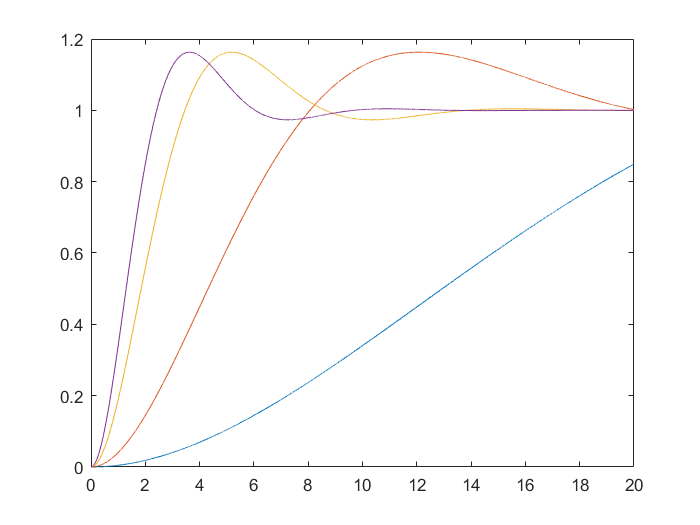

wn=[0.1,0.3,0.7,1];
csei=0.5;
s=0:0.001:20;
for i=1:4
den=[1 2*csei*wn(i) wn(i)^2];
sys=tf(wn(i)^2,den);
y(:,i)=step(sys,s);
end
plot(s,y)

[ymax,tprow]=max(y(:,3));
mp=ymax;
tp=tprow*0.001;
tes=find(abs(y(:,3)-1)<=0.05)*0.001;
ts=max(tes);
tr1=find(abs(y(:,3)-1)<=0.1);%因为是离散的值，所以找离1最近的那个
tr=min(tr1)*0.001;
mp

mp = 1.1630

tp

tp = 5.1830

ts

ts = 20.0010

tr

tr = 3.0380

datestr(now,21)

ans = 'Mar.26,2021 20:26:55'

1.10 连续系统仿真实例

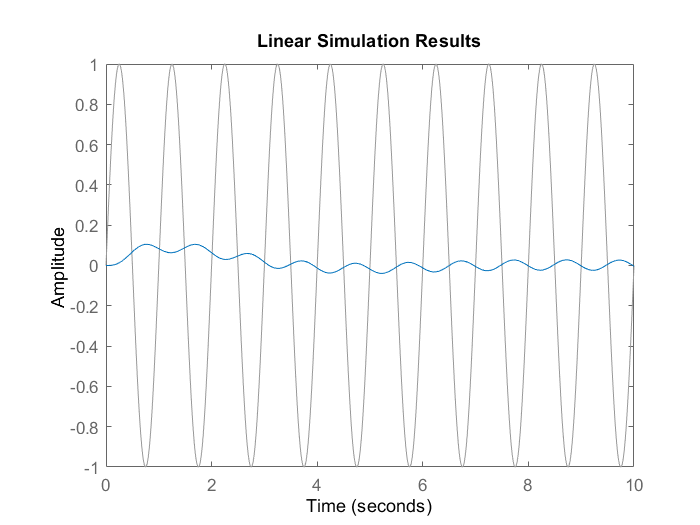

num10=1;
den10=[0.1 0.1 0.3];
sys10=tf(num10,den10);
t=0: 0.01: 10;
u=sin(2*pi*t); 
lsim(num,den,u,t)

datestr(now,21)

ans = 'Mar.26,2021 20:26:55'